# Radar Systems Laboratory - A.A. 2022/2023

Master Degree in Telecommunication Engineering, University of Pisa

## Third example: windowing | 29-11-2022

This live script initialises the serial connection with the evaluation board, it sets the parameters of the radar and starts the acquisition. **The trigger mechanism is automatic and the code reads every frame sent by the board. **The plot is updated every time a frame is received.

### Initialisation and data loading

clear
close all
clc

load('target30.mat')

### Radar setting

c = 3e8;
calFactor = 37.5;

zeroPadding = 4;
nfft = zeroPadding*nSamples;

maxRange = ((nSamples + calFactor)*c)/(4*BW);
rangeVec = (0:2*maxRange/nfft:maxRange - maxRange/nfft)*100;

The following equation can be found in the SiRad Simple datasheet: 

$T_{ramp} = t_{smp}\cdot \frac{n° Samples + 37.5}{36MHz}$ , $\qquad \qquad \qquad (1)$ 

where $t_{\textrm{smp}}$ is expressed in clock cycles, the values can be found in the **Table 19 **of the datasheet. The FMCW equation **[1]**:

$\frac{f_b}{\tau} = \frac{B}{T_{ramp}} $ ,$\qquad \qquad \qquad (2)$ 

where $f_b$ is the beat frequency, $\tau \;$is the transit time delay and $B$ is the bandwidth of the system, can be used to calculate the maximum achievable range, by considering that:

$f_b^{max} = \frac{f_s}{2} = \frac{36MHz}{2t_{smp}}$   and   $\tau = \frac{2R_{max}}{c}$ , $\qquad \qquad \qquad (3)$ 

By substituing equations $\left(1\right)$and $\left(3\right)$ in equation $\left(2\right)$, we can write the maximum achievable range:


$$R_{max} = \frac{\left(n° Samples + 37.5\right)\cdot c}{4\cdot B}$$
  
$$\qquad \qquad \qquad (2)$$
 

- **Note: **the "calibration factor" (i.e., 37.5) is different from the one written in the datasheet. 

### Processing and plot

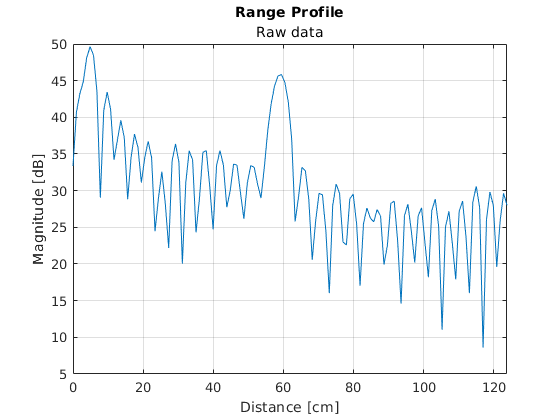

windowHann = hann(nSamples).';

rangeProfile = fft(complexData,nfft);
curveToPlot = abs(rangeProfile(1:end/2));

rangeProfileWHann = fft(complexData.*windowHann,nfft);
curveToPlotWHann = abs(rangeProfileWHann(1:end/2));

figure
plot(rangeVec,20*log10(curveToPlot))
title('Range Profile','Raw data')
xlabel("Distance [cm]")
ylabel("Magnitude [dB]")
xlim([0 rangeVec(end)])
grid on

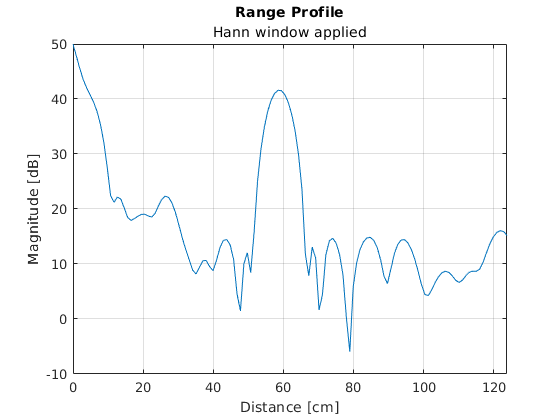


figure
plot(rangeVec,20*log10(curveToPlotWHann))
title('Range Profile','Hann window applied')
xlabel("Distance [cm]")
ylabel("Magnitude [dB]")
xlim([0 rangeVec(end)])
grid on

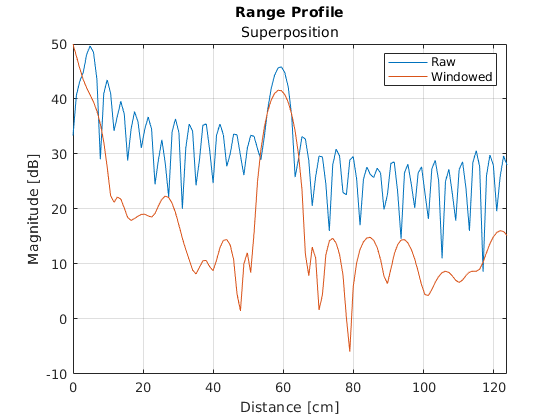


figure
plot(rangeVec,20*log10(curveToPlot))
hold on
plot(rangeVec,20*log10(curveToPlotWHann))
title('Range Profile','Superposition')
xlabel("Distance [cm]")
ylabel("Magnitude [dB]")
xlim([0 rangeVec(end)])
legend('Raw','Windowed')
grid on

### Windows comparison

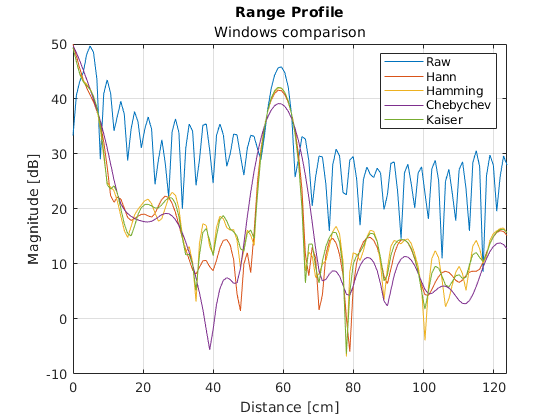

windowHamming = hamming(nSamples).';
windowCheb = chebwin(nSamples).';
windowKaiser = kaiser(nSamples,5).';

rangeProfileWHamming = fft(complexData.*windowHamming,nfft);
curveToPlotWHamming = abs(rangeProfileWHamming(1:end/2));

rangeProfileWCheb = fft(complexData.*windowCheb,nfft);
curveToPlotWCheb = abs(rangeProfileWCheb(1:end/2));

rangeProfileWKaiser = fft(complexData.*windowKaiser,nfft);
curveToPlotWKaiser = abs(rangeProfileWKaiser(1:end/2));

figure
plot(rangeVec,20*log10(curveToPlot))
hold on
plot(rangeVec,20*log10(curveToPlotWHann))
plot(rangeVec,20*log10(curveToPlotWHamming))
plot(rangeVec,20*log10(curveToPlotWCheb))
plot(rangeVec,20*log10(curveToPlotWKaiser))
title('Range Profile','Windows comparison')
xlabel("Distance [cm]")
ylabel("Magnitude [dB]")
xlim([0 rangeVec(end)])
legend('Raw','Hann','Hamming','Chebychev','Kaiser')
grid on

### References

**[1] **James A. Scheer, James L. Kurtz (editors). “Coherent Radar Performance Estimation”. Boston: Artech House (1993), ISBN 0-89006-628-0.